# Обработка изображений

## Импорт изображений

Для импорта изображений используется уже знакомая вам функция `imread.` Функция поддерживает форматы BMP, CUR, GIF, HDF, JPEG, PBM, PCX, PGM, PNG, PPM, RAS, TIFF, XWD.  

image_1 = imread("BFS_rocket.jpg");

Посмотреть изображение можно с помощью функции `imshow`.

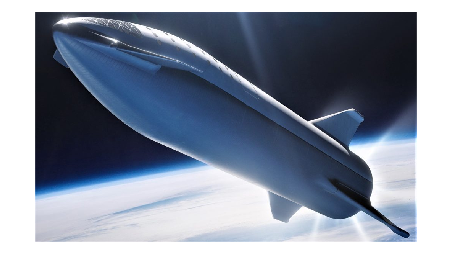

imshow(image_1)

Формат JPG считывается в виде матрицы $W\times H\times 3$, где W - ширина изображения в пикселях, H - высота изображения в пикселях. При этом 3-я координата в матрице отвечает за каналы цвета (RGB). Большинство операций по работе с изображениями происходит именно в этом формате.

С этой матрицей можно работать непосредственно, изменяя её значения.

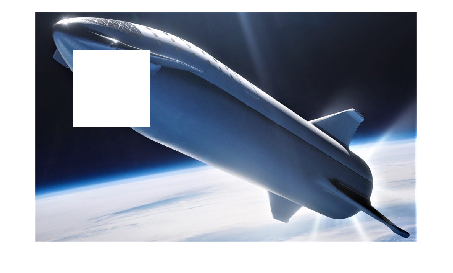

image_1(100:300,100:300,:) = 255;
imshow(image_1)

Однако, здесь есть тонкости. Посмотрите, что происходит при чтении изображения формата PNG.

Вот как изображение выглядит в оригинале:

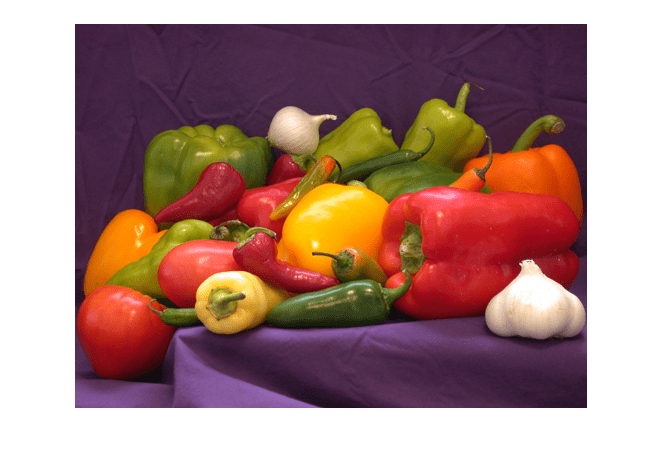

И вот, что происходит, если открыть его:

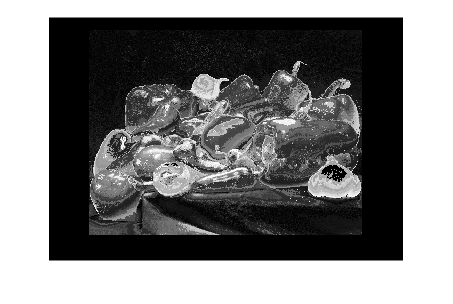

image_2 = imread("peppers.png");
imshow(image_2)

Такой эффект связан с тем, что изображение может быть индексированным (цвет пикселя выбирается из таблицы – палитры). Такое возможно в форматах TIFF и PNG. Такие изображение нужно считывать вместе с палитрой (colormap – цветовой картой):

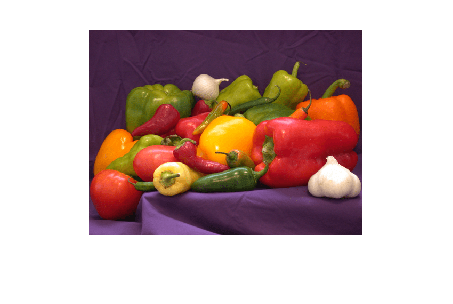

[image_2, map] = imread("peppers.png");
imshow(image_2, map)

Можно задать и свою цветовую карту. В MATLAB есть несколько предустановленных для вывода графиков, например, `hot:`

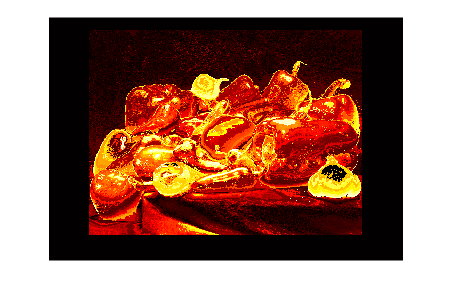

newmap = hot(256);
imshow(image_2, newmap)

Чтобы перевести изображение в RGB, необходимо использовать функцию `ind2rgb`.

image_2_rgb = ind2rgb(image_2, map);
imshow(image_2_rgb)

## Сохранение изображений

Изображения можно сохранить с помощью функции `imwrite`.

imwrite(image_2, newmap, "hot_peppers.png");